# Exergy Cost Calculator Demo

Use ExergyCostCalculator function to compute direct and generalized exergy cost

#### Select the model file

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(file);

#### Select the parameters

States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(1));
param.CostTables=cType.DEFAULT_COST_TABLES;
if data.isResourceCost
    Samples=convertCharsToStrings(data.ResourceSamples);
    ResourceSample=convertStringsToChars(Samples(1));
    CostTables='ALL';
end

#### Compute Exergy Cost

res=ExergyCostCalculator(data,'State',State,...
    'CostTables',CostTables, ...
    'ResourceSample',ResourceSample,...
    'Show',true);

Flows Exergy Cost

Key          B(kW)      B*(kW)     Be*(kW)     Br*(kW)     k*(J/J)    ke*(J/J)    kr*(J/J)
———————————————————————————————————————————————————————————————————————————————————————————
B1          83.570     133.029     115.091      17.938      1.5918      1.3772      0.2146
B2          17.900      28.494      24.652       3.842      1.5918      1.3772      0.2146
B3          15.790      25.135      21.746       3.389      1.5918      1.3772      0.2146
B4           5.784       9.207       7.966       1.242      1.5918      1.3772      0.2146
B5           7.877      14.307      12.185       2.122      1.8163      1.5469      0.2694
B6           9.420      17.995      15.091       2.904      1.9103      1.6020      0.3083
QBLR       100.000     100.000     100.000       0.000      1.0000      1.0000      0.0000
WP           2.447       4.894       4.220       0.674      2.0000      1.7244      0.2756
WN          50.000     100.000      86.220      13.780      2.0000    

#### Show Irreversibility Cost Graph

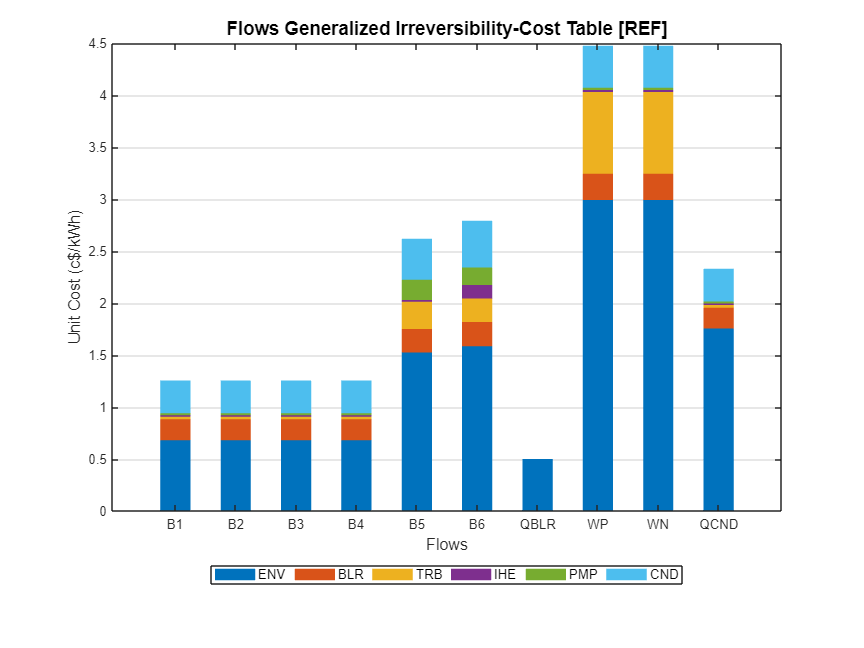

showGraph(res,cType.Tables.FLOW_GENERAL_ICT);